### **Método de Newton-Raphson**** (Tangentes)**


$$x^{k+1} = x^{k}-\frac{f(x^{k})}{f'(x^{k})}$$


Vamos encontrar o zero da função $f(x) = e^{-x}-x$ no intervalo de $[0,1]$utilizando o método de Newton-Raphson, com  chute inicial $x^{0} = 0$ e erro relativo igual ou menor que $10^{-2}$.

**Graficamente, **

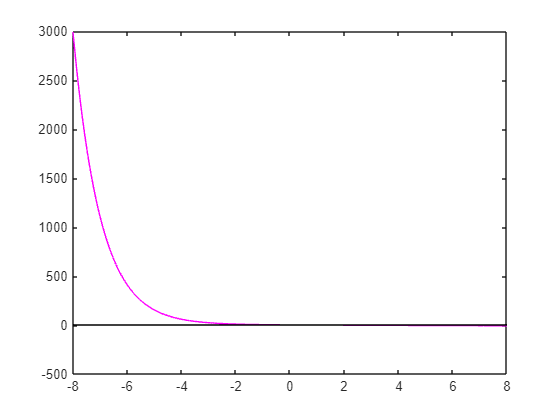

x= -8:0.01:8;
y = fun(x);
plot(x,y,'magenta')
y1 = 0*x;
hold on 
plot(x,y1, 'black')
hold off

**Implementação do Newton-Raphson:**

format long
%Chute inicial
x0 = 0;
fx0 = fun(x0);
tol = 10^-2;
k = 0;
while(abs(fx0) > tol)
    x = x0 - (fun(x0)/dfun(x0)); %atualizando o zero da função usando o metodo de newton-raphson
    x0 = x;
    fx0 = fun(x0);
    k = k+1;
    xk(k,:) = x0;
    fk(k,:) = fx0;
end
[xk,fk]

ans =    0.500000000000000   0.106530659712633
   0.566311003197218   0.001304509806020


### Exemplo:

format long
%Chute inicial
x02 = 0.5;
fx02 = fun2(x02);
tol2 = 10^-2;
k2 = 0;
while(abs(fx02) > tol2)
    x2 = x02 - (fun2(x02)/dfun2(x02)); %atualizando o zero da função usando o metodo de newton-raphson
    x02 = x2;
    fx02 = fun2(x02);
    k2 = k2+1;
    xk2(k2,:) = x02;
    fk2(k2,:) = fx02;
end
[xk2,fk2]

ans = 1.0e+17 *

   0.000000000000001   1.351149044839137
   0.000000000000000   0.471116541297115
   0.000000000000000   0.164268180724785
   0.000000000000000   0.057276773013183
   0.000000000000000   0.019971175868198
   0.000000000000000   0.006963518448686
   0.000000000000000   0.002428028750295
   0.000000000000000   0.000846601277171
   0.000000000000000   0.000295191612711
   0.000000000000000   0.000102926951051


**Definindo as funções que serão utilizadas:**

function y = fun(x)
    y = exp(-x)-x;
end
function y = dfun(x)
    y = -exp(-x)-1;
end

Função: $f(x) = x^{10}-1$

function y = fun2(x)
    y = x^10-1;
end
function y = dfun2(x)
    y = 10*x^9;
end